# Optimizing fuselage design

This work aims to design and optimize the mass, and cost of a civil aircraft fuselage against buckling constraints

The fuselage is designed as a semi-monocoque structure reinforced by longitudinal stringers (longerons) and circumferential frames to withstand the following loads during maneuvers. The objective is to identify the minimum-mass configuration that satisfies all structural constraints including: 

- Pressurization stresses

- Shear flow loads

- Skin buckling

- Stringer buckling and crippling 

- Free stiffness requirements 

Material selection is first performed using Ashby performance indices, after which a discrete optimization search is conducted over skin thickness, stringer geometry, and frame spacing. 

## Assumptions (General modelling assumptions)

- Shear flow is constant between adjacent stringers so that the analysis simplies to idealized sections, with the stringers/boom carrying all the direct stresses while the skin is effective only in shear (Meg)

- 
$$M_1 =M_2$$


- Skin thickness ${t^{\textrm{cy}} }_s \;\textrm{is}\;\textrm{constant}\;$across fuselage length 

- $B_{0\;}$is same for all the stringers 

- The classical thin-walled boom idealisation is used in this study (assumption 1) 

This approach is consistent with treatments found in:

- Aircraft Structures for Engineering Students by T. H. G. Megson

- Analysis and Design of Flight Vehicle Structures by E. F. Bruhn

and works well with semi-monocoque structures, and simplifies stress calculations.

Ultimate Shear forces and load cases are considered. Values from airworthiness model is rounded to nearest thousand.

The summary of the optimization process is found in fig 1.

clc; clear;

% GLOBAL CONSTANTS 
g = 9.81;

% Geometry
D_fus = 3.55;                 % Fuselage diameter [m]
R_fus = D_fus/2;              % Fuselage radius [m]
L_fus = 28.896;               % Fuselage barrel length [m]

% Pressure
P_cabin  = 0.754;             % bar
P_cruise = 0.385;             % bar
P_diff   = (P_cabin - P_cruise)*1e5;   % Pa

% Load cases
Mx = 2.3e6;            % Bending moment [Nm]
My = 1.15e6;           % Bending moment [Nm]
Tq = 400000;           % Torque [Nm]
Q  = 4e5;              % Radial load[N]
P = 47000;             % Tangential load [N]

pi_val = pi;
Torque = Tq;
ShearQ = Q;

% Safety
FS = 1.5;
nu = 0.33;

## MATERIAL SELECTION USING ASHBY INDICES

This section selects candidate materials for fuselage skins and stringer/frame structures using Ashby performance indices. Skins are governed primarily by strength requirements (tension and compression), while stringers and frames are stiffness-dominated structural members.

The material with the highest performance index in each categoryis selected for the subsequent structural optimizatio Five alloys of aluminum are considered in this analyis: Al 2024-T3, Al 7075-T6, Al 2024-T6, Al 2024-T851 (with improved fracture toughness properties), Al 7068-T6511 (with improved tensile strength) and Al 6000 (due to improved cost). The Al-2000x series (aluminum-copper 4.5%-magnesuim 1.5% -maganese -0.6%), 

% MATERIAL DATABASE 
% PROPERTY DEFINITIONS 

loadTbl = table( ...
    ["Yield Strength"; "Compressive Strength"; "Tensile Strength"; ...
     "Fracture Toughness"; "Young's Modulus"; "Shear Modulus"], ...
    ["YS"; "CS"; "TeS"; "FaS"; "ST"; "ToS"], ...
    ["\sigma_y"; "\sigma_c"; "\sigma_t"; "K_{IC}"; "E"; "G"], ...
    'VariableNames', {'Metric', 'Abbreviation', 'MechanicalProperty'} ...
);

% MATERIAL DATA 

% Mechanical properties (MPa)
MProp = {
    [325 325 470 25 73e3 27e3];   % Al 2024-T3
    [480 390 560 20 70e3 26e3];   % Al 7075-T6
    [410 410 470 20 72e3 27e3];   % Al 2024-T6
    [420 420 480 35 71e3 27e3];   % Al 2024-T851 
    [683 641 710 18 72e3 27e3];   % Al 7068-T6511 
};


rho_mat = [
    2780    % 2024-T3
    2810    % 7075-T6
    2780    % 2024-T6
    2780    % 2024-T851
    2850    % 7068-T6511
];

cost_mat = [
    1.0
    1.5
    1.05
    1.2
    2.2
];

materialNames = ["Al 2024-T3", "Al 7075-T6", "Al 2024-T6", "Al 2024-T851", "Al 7068-T6511"];
nMat = numel(MProp);

% MATERIAL INDEX FUNCTION 

% Ashby's performance indices
MatProp = @(YS,CS,TeS,FaS,ST,ToS,rho_mat,cost_mat) ...
    [ ...
      (YS.^(2/3))  /(rho_mat * cost_mat);   % Yield strength index
      (CS.^(2/3))  /(rho_mat * cost_mat);   % Compression strength index
      (TeS.^(2/3)) /(rho_mat * cost_mat);   % Tensile strength index
      (FaS.^(2/3)) /(rho_mat * cost_mat);   % Fracture toughness index
      (ST)         /(rho_mat * cost_mat);   % Young's modulus index
      (ToS)        /(rho_mat * cost_mat)    % Shear modulus index
    ];

% BUILDING MATERIAL TABLES 

MatTbl = cell(nMat,1);

for i = 1:nMat

    p = MProp{i};

    value = MatProp( ...
        p(1), p(2), p(3), p(4), p(5), p(6), ...
        rho_mat(i), cost_mat(i));

    T = loadTbl;
    T.MProp   = p(:);
    T.Density = repmat(rho_mat(i), height(T), 1);
    T.Cost    = repmat(cost_mat(i), height(T), 1);
     T.Value   = value(:);

    MatTbl{i} = T;
    % Display
    fprintf('Material: %s\n', materialNames(i));
    disp(T)

end

Material: Al 2024-T3


            Metric            Abbreviation    MechanicalProperty    MProp    Density    Cost      Value  
    ______________________    ____________    __________________    _____    _______    ____    _________

    "Yield Strength"             "YS"             "\sigma_y"          325     2780       1       0.017004
    "Compressive Strength"       "CS"             "\sigma_c"          325     2780       1       0.017004
    "Tensile Strength"           "TeS"            "\sigma_t"          470     2780       1       0.021745
    "Fracture Toughness"         "FaS"            "K_{IC}"             25     2780       1      0.0030755
    "Young's Modulus"            "ST"             "E"               73000     2780       1         26.259
    "Shear Modulus"

Material: Al 7075-T6


            Metric            Abbreviation    MechanicalProperty    MProp    Density    Cost      Value  
    ______________________    ____________    __________________    _____    _______    ____    _________

    "Yield Strength"             "YS"             "\sigma_y"          480     2810      1.5      0.014544
    "Compressive Strength"       "CS"             "\sigma_c"          390     2810      1.5      0.012664
    "Tensile Strength"           "TeS"            "\sigma_t"          560     2810      1.5      0.016119
    "Fracture Toughness"         "FaS"            "K_{IC}"             20     2810      1.5     0.0017481
    "Young's Modulus"            "ST"             "E"               70000     2810      1.5        16.607
    "Shear Modulus"

Material: Al 2024-T6


            Metric            Abbreviation    MechanicalProperty    MProp    Density    Cost      Value  
    ______________________    ____________    __________________    _____    _______    ____    _________

    "Yield Strength"             "YS"             "\sigma_y"          410     2780      1.05     0.018907
    "Compressive Strength"       "CS"             "\sigma_c"          410     2780      1.05     0.018907
    "Tensile Strength"           "TeS"            "\sigma_t"          470     2780      1.05     0.020709
    "Fracture Toughness"         "FaS"            "K_{IC}"             20     2780      1.05    0.0025242
    "Young's Modulus"            "ST"             "E"               72000     2780      1.05       24.666
    "Shear Modulus"

Material: Al 2024-T851


            Metric            Abbreviation    MechanicalProperty    MProp    Density    Cost      Value  
    ______________________    ____________    __________________    _____    _______    ____    _________

    "Yield Strength"             "YS"             "\sigma_y"          420     2780      1.2      0.016812
    "Compressive Strength"       "CS"             "\sigma_c"          420     2780      1.2      0.016812
    "Tensile Strength"           "TeS"            "\sigma_t"          480     2780      1.2      0.018377
    "Fracture Toughness"         "FaS"            "K_{IC}"             35     2780      1.2     0.0032074
    "Young's Modulus"            "ST"             "E"               71000     2780      1.2        21.283
    "Shear Modulus"

Material: Al 7068-T6511


            Metric            Abbreviation    MechanicalProperty    MProp    Density    Cost      Value  
    ______________________    ____________    __________________    _____    _______    ____    _________

    "Yield Strength"             "YS"             "\sigma_y"          683     2850      2.2      0.012369
    "Compressive Strength"       "CS"             "\sigma_c"          641     2850      2.2      0.011857
    "Tensile Strength"           "TeS"            "\sigma_t"          710     2850      2.2      0.012693
    "Fracture Toughness"         "FaS"            "K_{IC}"             18     2850      2.2     0.0010954
    "Young's Modulus"            "ST"             "E"               72000     2850      2.2        11.483
    "Shear Modulus"

% MATERIAL OPTIMIZATION TARGETS 

% Index locations
idx_CS  = find(loadTbl.Abbreviation == "CS");
idx_TeS = find(loadTbl.Abbreviation == "TeS");
idx_ST  = find(loadTbl.Abbreviation == "ST");

% Containers
skinScore      = zeros(nMat,1);
stringerScore  = zeros(nMat,1);

for i = 1:nMat
    V = MatTbl{i}.Value;

    % Skins: tension + compression
    skinScore(i) = V(idx_TeS) + V(idx_CS);

    % Stringers & frames: stiffness-dominated
    stringerScore(i) = V(idx_ST);
end


Materials are ranked using Ashby-type performance indices. Skin materials are evaluated based on their ability to resist tensile and compressive stresses. Stringers and frames are stiffness-driven members and are therefore ranked using stiffness-related indices. The materials with the highest scores are selected for the structural optimization stage.

% MATERIAL SELECTION

[~, i_skin] = max(skinScore);
[~, i_str ] = max(stringerScore);

% FINAL OUTPUT TABLE

FuselageComponents = ...
    ["Upper skin"; "Lower skin"; "Stringer"; "Light frames"; "Heavy frames"];

ChosenMaterial = [
    materialNames(i_skin)
    materialNames(i_skin)
    materialNames(i_str)
    materialNames(i_str)
    materialNames(i_str)
];

ResultTbl = table(FuselageComponents, ChosenMaterial);
disp('      OPTIMIZED FUSELAGE MATERIALS         ')

      OPTIMIZED FUSELAGE MATERIALS         


disp(ResultTbl)

    FuselageComponents    ChosenMaterial
    __________________    ______________

      "Upper skin"         "Al 2024-T6" 
      "Lower skin"         "Al 2024-T6" 
      "Stringer"           "Al 2024-T3" 
      "Light frames"       "Al 2024-T3" 
      "Heavy frames"       "Al 2024-T3" 



%% --- OPTIONAL: DISPLAY SCORES ----

ScoreTbl = table(materialNames.', skinScore, stringerScore, ...
    'VariableNames', {'Material','SkinIndex','StringerIndex'});
disp('      MATERIAL PERFORMANCE INDICES         ')

      MATERIAL PERFORMANCE INDICES         


disp(ScoreTbl)

       Material        SkinIndex    StringerIndex
    _______________    _________    _____________

    "Al 2024-T3"       0.038748        26.259    
    "Al 7075-T6"       0.028783        16.607    
    "Al 2024-T6"       0.039616        24.666    
    "Al 2024-T851"     0.035188        21.283    
    "Al 7068-T6511"     0.02455        11.483    



% MATERIAL SELECTION FROM ASHBY

% Skin material (upper & lower)
mat_skin   = MProp{i_skin};
rho_skin   = rho_mat(i_skin);
cost_skin  = cost_mat(i_skin);
name_skin  = materialNames(i_skin);

% Stringer + Frames material
mat_str    = MProp{i_str};
rho_str    = rho_mat(i_str);
cost_str   = cost_mat(i_str);
name_str   = materialNames(i_str);

fprintf('\n MATERIALS USED IN STRUCTURAL OPTIMIZATION \n');


 MATERIALS USED IN STRUCTURAL OPTIMIZATION 


fprintf('Skin (upper & lower): %s\n', name_skin);

Skin (upper & lower): Al 2024-T6


fprintf('Stringers + Frames:   %s\n\n', name_str);

Stringers + Frames:   Al 2024-T3



% Convert properties (MPa → Pa)
sigma_y_skin = mat_skin(1)*1e6 / FS;
E_skin       = mat_skin(5)*1e6;

sigma_y_str  = mat_str(1)*1e6 / FS;
E_str        = mat_str(5)*1e6;

% DESIGN SPACE 
% SKIN-STRINGER DESIGN SPACE 


The following parameters define the structural design space explored during optimization. The fuselage is modeled as a stiffened shell consisting of skins, longitudinal stringers, and circumferential frames.

Variables include:

  - skin thickness

  - number of stringers

  - stringer cross-sectional area

  - stringer web and flange geometry

  - frame spacing and frame geometry

The optimizer searches this discrete parameter space to identify configurations that satisfy all structural constraints while minimizing fuselage mass.


t_skin_vec  = 1.5e-3:0.2e-3:4e-3;

n_str_vec   = 40:10:200;
A_str_vec   = 1e-4:0.25e-4:3e-4;
h_web_vec = 0.03:0.005:0.07;  
b_fl_vec = 0.03:0.005:0.08; 

% FRAME GEOMETRY SEARCH SPACE 
L_frame_vec = 0.3:0.05:1;
wh_range = 0.01:0.002:0.05;   % frame web height [m]
fw_range = 0.02:0.002:0.06;   % frame flange width [m]

% CONSTRAINTS 
sigma_allowable = sigma_y_skin;

## Constraints

Several structural failure modes are evaluated for each candiate design configuratio

- Skin yielding due to pressurization stresses 

- Skin shear yielding (von Mises criterion)$\tau_{\mathrm{yield}} =\frac{\sigma_y }{\sqrt{\left(3\right)}}$

- Skin shear buckling

- Skin axial plate buckling between stringers

- Stringer euler (column) buckling  $\sigma_{\mathrm{cr}} =\frac{\pi^2 E}{{\left(\frac{\mathrm{KL}}{r_g }\right)}^2 }$

- Frame stiffness requirement 

- Skin yield (between stringers)  $\sigma_{\textrm{skin}\;} \le \sigma_{\textrm{allow},\textrm{skin}}$, where $\sigma_{\textrm{skin}} =\frac{\textrm{My}}{I}$ 

- Loacal element buckling of stringer web and flanges  $\sigma =k\;\frac{\pi^2 E}{12\left(1-v^2 \right)}{\left(\frac{t_f }{b}\right)}^2 \;$c     $k=4,$and $n=1$ because 

- Stringer crippling (Gerard emperical method). OEF (One Edge Free Buckling) (references: [Buckling and Crippling by Collier Aerospace, ](https://cdn.collieraerospace.com/wp-content/uploads/2023/04/Buckling-Crippling.pdf) [Local Stability by Abott Aerospace, ](https://www.abbottaerospace.com/aa-sb-001/15-local-stability-isotropic-materials/15-5-crippling/)The crippling strength of compression elements pdf by Gerard)


$$F_{\textrm{cc}\;} =0\ldotp 56\;\frac{F_{\textrm{cy}}^{0\ldotp 6} \cdot E^{0\ldotp 4} }{{\left(\frac{b}{t}\right)}^{0\ldotp 8} }$$
   

flange: one edge free (0.56) 

web: partially restrained (0.67)

## Frame assumptions: 

- Equal flange and web thickness

- No corner radii

## Stringer assumptions: 

- No corner radii

## Component Shapes 

- Stringer: L-section

- Frame: C-section

## FINAL DESIGN OPTIMIZATION 

After all feasible configurations, the design with the minimum total stuctural mass is selected as the optimal fuselage configuration. The mass budget is about 3,630 kg and the design is expected to be below the mass budget. 

The final output includes: 

- Structural geometry

- Stress levels 

- Margins of safety

- Componenet masses 

- Material cost (approx. or assumed) 

% PARALLEL OPTIMIZATION 
if isempty(gcp('nocreate'))
    parpool;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 8 workers.


% OPTIMIZATION

Results_cell = cell(length(t_skin_vec),1);

ResultTemplate = struct( ...
    'material_skin',          "", ...
    'material_stringer',      "", ...
    't_skin',                 NaN, ...
    'sigma_hoop',             NaN, ...
    'sigma_long',             NaN, ...
    'tau_skin',               NaN, ...
    'sigma_skin_cr',          NaN, ...
    'b_str',                  NaN, ...
    'n_stringers',            NaN, ...
    'A_stringer',             NaN, ...
    'sigma_stringer_max',     NaN, ...
    'sigma_euler',            NaN, ...
    'L_frame',                NaN, ...
    't_frame',                NaN, ...
    'I_frame_req',            NaN, ...
    'I_frame',                NaN, ...
    'm_skin',                 NaN, ...
    'm_stringers',            NaN, ...
    'm_frames',               NaN, ...
    'm_total',                NaN, ...
    'MS_skin_yield',          NaN, ...
    'MS_skin_buckling',       NaN, ...
    'MS_skin_shear_buckling', NaN, ...
    'MS_skin_interaction',    NaN, ...  
    'MS_stringer_yield',      NaN, ...
    'MS_stringer_buckling',   NaN, ...
    'MS_crippling',           NaN, ...  
    'MS_frame',               NaN, ...
    'MS_min',                 NaN, ...
    'sigma_cripple',          NaN, ...
    'cost_skin',              NaN, ...
    'cost_stringers',         NaN, ...
    'cost_frames',            NaN, ...
    'cost_total',             NaN, ...
    'h_web',                  NaN, ...
    'b_fl',                   NaN, ...
    't_str',                  NaN, ...
    'r_g',                    NaN, ...
    'wh_frame',               NaN, ...
    'fw_frame',               NaN, ...
    'n_frames',               NaN  ...
);


parfor it = 1:length(t_skin_vec)
     
    % Loop over canditate skin thickness values
    t_skin = t_skin_vec(it);
    localResults = {};

    % Pressurization stresses
    sigma_hoop = (P_diff*R_fus)/t_skin;
    sigma_long = (P_diff*R_fus)/(2*t_skin);

    if max([sigma_hoop, sigma_long]) > sigma_allowable
        continue
    end

    for n_str = n_str_vec
        b_skin = 2*pi_val*R_fus/n_str;

    % Skin axial buckling
    fxe_fo_ratio = 1.745;  
    sigma_skin_cr_elastic = 4.0*pi_val^2*E_skin/(12*(1-nu^2))*(t_skin/b_skin)^2;
    sigma_skin_cr = sigma_skin_cr_elastic / fxe_fo_ratio;       % Plasticity correction from Bruhn plate buckling charts 
       
   
    % Shear flow 
    phi = linspace(0,2*pi_val,180);
    alpha = -pi_val/2;
        q = (Torque + P*R_fus)/(2*pi_val*R_fus^2) ...
          + (P*cos(phi - alpha))/(pi_val*R_fus) ...
          + (ShearQ*sin(phi - alpha))/(pi_val*R_fus);
          
        % skin shear yield Von Mises
        tau_skin = max(abs(q))/t_skin;
        tau_allow = sigma_y_skin/sqrt(3);
        if tau_skin > tau_allow;     continue; end

        % skin shear buckling
        tau_skin_cr = 9.9 * E_skin * (t_skin/b_skin)^2;
        if tau_skin > tau_skin_cr;  continue;  end

         %  Boom coordinates (fixed for this n_str) 
        theta = linspace(0,2*pi_val,n_str+1);
        theta(end) = [];
        x = R_fus*cos(theta);
        y = R_fus*sin(theta);

        for A_str = A_str_vec
            for h_web = h_web_vec
                for b_fl = b_fl_vec

                % Z-STRINGER GEOMETRY
                t_str = A_str / (h_web + 2*b_fl);
                A_web = t_str*h_web;
                A_fl  = 2*(t_str*b_fl);
                A_str_actual = A_web + A_fl;

                y_web = h_web/2;
                y_fl  = t_str/2;
                y_bar = (A_web*y_web + A_fl*y_fl)/A_str_actual;

                I_web = (t_str*h_web^3)/12 + A_web*(y_web - y_bar)^2;
                I_fl  = (b_fl*t_str^3)/12  + A_fl*(y_fl  - y_bar)^2;
                I_str = I_web + I_fl;
                r_g   = sqrt(I_str/A_str_actual);

                
                % BOOM AREA ITERATION (NIU-BRUHN)
                B0 = A_str_actual*ones(1,n_str);
                Bs = 15*t_skin^2*ones(1,n_str);
                tol = 1e-4;
                iter_max = 50;

                for iter = 1:iter_max
                    B = B0 + Bs;
                    Ix = sum(B .* y.^2);
                    Iy = sum(B .* x.^2);
                    sigma = (My/Iy).*x + (Mx/Ix).*y;
                    
                    sigma_m = circshift(sigma,  1);
                    sigma_p = circshift(sigma, -1);
                    Bs_new = t_skin*b_skin/6 .* (2 + sigma_m./sigma + sigma_p./sigma);
                    Bs_new(abs(sigma) < 1e-8) = 0;
                    Bs_new  = max(0, Bs_new);

                    if max(abs(Bs_new - Bs)./(Bs + eps)) < tol
                        break
                    end
                    Bs = Bs_new;
                end

                % FINAL STRESSES
                B = B0 + Bs;
                Ix = sum(B .* y.^2);
                Iy = sum(B .* x.^2);
                
                sigma_raw      = (My/Iy).*x + (Mx/Ix).*y;  % signed (negative = compression)
                sigma_str_comp = max(0, -sigma_raw);         % compressive booms (positive)
                sigma_str_tens = max(0,  sigma_raw);         % tensile booms (positive)

                if max(abs(sigma_raw)) > sigma_y_str
                    continue
                end

                % Compressive stress in panel for stringers/local buckling                 
                sigma_skin_comp = max(0, max(sigma_str_comp) - sigma_long);
                if sigma_skin_comp > sigma_skin_cr
                        continue
                end
                    R_c            = sigma_skin_comp / max(sigma_skin_cr, eps);
                    R_s            = tau_skin        / max(tau_skin_cr,   eps);
                    MS_interaction = 1 - R_c - R_s^2;

                    if MS_interaction < 0
                        continue
                    end

                % Local element buckling
                sigma_comp_web = 5 * E_str * (t_str/h_web)^2;
                sigma_comp_fl  = 0.43 * E_str * (t_str/b_fl)^2;

                if max(sigma_str_comp) > min(sigma_comp_web, sigma_comp_fl)
                    continue 
                end 

                % CRIPPLING CHECK (Gerard method)
                % % Z-section: both web and flange have one free edge
                % % Gerard crippling — one free edge for both L-section legs
                F_cc_web = 0.67 * (sigma_y_str^0.6 * E_str^0.4) / (h_web/t_str)^0.8;
                F_cc_fl  = 0.56 * (sigma_y_str^0.6 * E_str^0.4) / (b_fl /t_str)^0.8;

                % Area-weighted section crippling stress
                sigma_cripple = (F_cc_web*A_web + F_cc_fl*A_fl) / A_str_actual;
                
                if max(sigma_str_comp) > sigma_cripple
                    continue
                end
                     
                
                
                   for L_frame = L_frame_vec            % fixed frame pitch [m]

                   % EULER BUCKLING FOR STRINGER
                    K = 1.0;
                    L_eff = K*L_frame;
                    sigma_euler = pi_val^2*E_str/(L_eff/r_g)^2;
                    if max(sigma_str_comp) > sigma_euler;  continue;  end

                        % Frame stiffness 
                        C_f = 1/16000;
                        EI_req = (C_f * max([Mx My]) * D_fus^2) / L_frame;
                        I_req  = EI_req / E_str;
                        
                        A_best = inf;

                        % FRAME GEOMETRY OPTIMIZATION
                        % Frame stiffness                     
                        for wh = wh_range
                            for fw = fw_range
                        
                                denom = (wh^3)/12 + (fw*wh^2)/2;
                                t_req = I_req / denom;
                        
                                if t_req <= 0 || t_req > 0.01
                                    continue
                                end
                        
                                A_try = (2*wh + fw) * t_req;
                        
                                if A_try < A_best
                                    A_best = A_try;
                                    wh_best = wh;
                                    fw_best = fw;
                                    t_best  = t_req;
                                end
                            end
                        end
                        
                        if isinf(A_best)
                            continue
                        end
                        
                        % Final geometry
                        A_frame = A_best;
                        wh_frame = wh_best;
                        fw_frame = fw_best;
                        t_frame  = t_best;
                        
                        I_frame = t_frame * ( (wh_frame^3)/12 + fw_frame*wh_frame^2/2 );
                        
                        % MASS
                        m_skin = 2*pi_val*R_fus*L_fus*t_skin*rho_skin;
                        m_stringers = n_str*A_str_actual*L_fus*rho_str;
                        n_frames = floor(L_fus/L_frame);
                        m_frames = n_frames*(2*pi_val*R_fus*A_frame*rho_str);

                        m_total = m_skin + m_stringers + m_frames;

                        tmp = ResultTemplate;

                        tmp.material_skin     = name_skin;
                        tmp.material_stringer = name_str;
                        
                        tmp.t_skin = t_skin;
                        tmp.sigma_hoop = sigma_hoop;
                        tmp.sigma_long = sigma_long;
                        tmp.tau_skin = tau_skin;
                        tmp.sigma_skin_cr = sigma_skin_cr;
                        tmp.b_str = b_skin;

                        tmp.n_stringers = n_str;
                        tmp.A_stringer  = A_str_actual;
                        tmp.sigma_stringer_max = max(abs(sigma_raw));
                        tmp.sigma_euler = sigma_euler;

                        tmp.h_web    = h_web;
                        tmp.b_fl     = b_fl;
                        tmp.t_str    = t_str;
                        tmp.r_g      = r_g;
                        tmp.wh_frame = wh_frame;
                        tmp.fw_frame = fw_frame;
                        tmp.n_frames = n_frames; 

                        tmp.L_frame = L_frame;
                        tmp.t_frame = t_frame;
                        tmp.I_frame_req = I_req;
                        tmp.I_frame = I_frame;

                        tmp.m_skin = m_skin;
                        tmp.m_stringers = m_stringers;
                        tmp.m_frames = m_frames;
                        tmp.m_total = m_total;

                        tmp.sigma_cripple = sigma_cripple;

                         % Margins of Safety 
                        tmp.MS_skin_yield           = sigma_y_skin / max([sigma_hoop sigma_long]) - 1;
                        tmp.MS_skin_buckling         = sigma_skin_cr / max(sigma_skin_comp, eps) - 1;
                        tmp.MS_skin_shear_buckling   = tau_skin_cr   / tau_skin - 1;
                        tmp.MS_skin_interaction      = MS_interaction;                          % 1 - R_c - R_s^2
                        tmp.MS_stringer_yield        = sigma_y_str   / max(abs(sigma_raw)) - 1;
                        tmp.MS_stringer_buckling     = sigma_euler    / max(sigma_str_comp) - 1;
                        tmp.MS_crippling             = sigma_cripple  / max(sigma_str_comp) - 1;
                        tmp.MS_frame                = I_frame / I_req - 1;

                        tmp.MS_min = min([
                            tmp.MS_skin_yield
                            tmp.MS_skin_buckling
                            tmp.MS_skin_shear_buckling
                            tmp.MS_skin_interaction
                            tmp.MS_stringer_yield
                            tmp.MS_stringer_buckling
                            tmp.MS_crippling
                            tmp.MS_frame ...
                            ]);

                        %  Cost 
                        tmp.cost_skin = m_skin*cost_skin;
                        tmp.cost_stringers = m_stringers*cost_str;
                        tmp.cost_frames = m_frames*cost_str;
                        tmp.cost_total = tmp.cost_skin + tmp.cost_stringers + tmp.cost_frames;
                        

                        if m_total <= 3630
                            localResults{end+1} = tmp;
                        end 
                        
                    end        % L_frame loop
                end            % b_fl loop
            end                % h_web loop 
        end                    % A_str loop 
    end                        % n_str loop

    Results_cell{it} = localResults;
end

% OPTIMAL DESIGN
Results = [Results_cell{:}];
Results = [Results{:}];    % <-- flatten cell of structs into struct array

if isempty(Results)
    error('No feasible design found under 3630 kg');
end
masses = [Results.m_total];
[~,idx] = min(masses);
best = Results(idx);

fprintf('\n===== OPTIMAL FUSELAGE DESIGN =====\n');


===== OPTIMAL FUSELAGE DESIGN =====


fprintf('\n===== OPTIMAL FUSELAGE DESIGN =====\n');


===== OPTIMAL FUSELAGE DESIGN =====


fprintf('Skin material: %s\n', best.material_skin);

Skin material: Al 2024-T6


fprintf('Stringer/frame material: %s\n', best.material_stringer);

Stringer/frame material: Al 2024-T3


fprintf('Total Mass: %.2f kg\n', best.m_total);

Total Mass: 3261.23 kg


fprintf('Skin Mass: %.2f kg\n', best.m_skin);

Skin Mass: 1523.03 kg


fprintf('Stringer Mass: %.2f kg\n', best.m_stringers);

Stringer Mass: 1686.95 kg


fprintf('Frame Mass: %.2f kg\n', best.m_frames);

Frame Mass: 51.24 kg


fprintf('Total Material Cost: %.2f\n', best.cost_total);

Total Material Cost: 3337.38


disp(best)

             material_skin: "Al 2024-T6"
         material_stringer: "Al 2024-T3"
                    t_skin: 0.0017
                sigma_hoop: 3.8528e+07
                sigma_long: 1.9264e+07
                  tau_skin: 5.6848e+07
             sigma_skin_cr: 6.9372e+07
                     b_str: 0.0797
               n_stringers: 140
                A_stringer: 1.5000e-04
        sigma_stringer_max: 8.6138e+07
               sigma_euler: 9.1306e+07
                   L_frame: 0.9000
                   t_frame: 3.2282e-04
               I_frame_req: 2.7574e-08
                   I_frame: 2.7574e-08
                    m_skin: 1.5230e+03
               m_stringers: 1.6869e+03
                  m_frames: 51.2448
                   m_total: 3.2612e+03
             MS_skin_yield: 6.0944
          MS_skin_buckling: 0.0374
    MS_skin_shear_buckling: 4.7102
       MS_skin_interaction: 0.0053
         MS_stringer_yield: 1.5153
      MS_stringer_buckling: 0.0600
              MS_crippling: 

## Heavy frames Guideline

This serves as a guideline for the circumferential evaluation of loads in sections that will be heavy frames like the bulkhead and at the landing gears. Radial, tangentail and torsionall load moments acting on the fuselage can be plotted below as a function of the circumferential angle $\phi$.

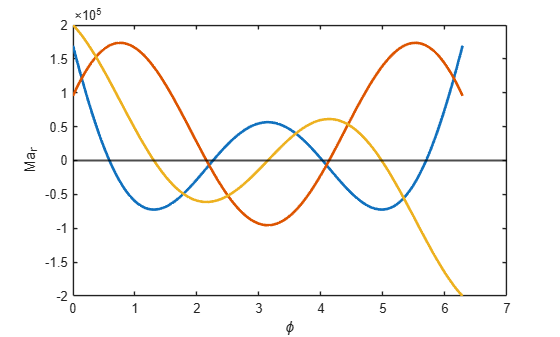

% HEAVY FRAMES CALCULATIONS 
% From a point 'a'

phi = linspace(0, 2*pi, 360);
m = length(phi);

% Radial load 
Ma_r_r = (Q * R_fus)/(2 * pi) .* (1 + (0.5 .* cos(phi)) - ((pi - phi).*sin(phi)));
Na_r_r = Q/(2*pi) .* (3/2*cos(phi) + (pi - phi).*sin(phi));
Sa_r_r = Q/(2*pi) .* ((pi - phi).*cos(phi) - 0.5.*sin(phi));

% Tangential load 
Ma_r_t = P*R_fus/(2*pi) .* ((pi - phi).*(1 -cos(phi)) - 3/2*sin(phi));
Na_r_t = P/(2*pi) .* ((pi - phi).*cos(phi) - 0.5.*sin(phi));
Sa_r_t = P/(2*pi) .* (1 + 0.5 .* cos(phi) - (pi - phi).*sin(phi));

% Moment load
Ma_r_m = Torque/(2*pi) .* ((pi - phi) - 2*sin(phi));
Na_r_m = Torque/(pi*R_fus) .* sin(phi);
Sa_r_m = Torque/(2*pi*R_fus) .* (1 + 2*cos(phi));
% Na_r_m = Torque/(2*pi*R_fus) .* (3/2.*cos(phi) + (pi - phi).*sin(phi));


% Assemble output matrix
Ma_r = [ ...
    Ma_r_r.' Na_r_r.' Sa_r_r.' ...m
    Ma_r_t.' Na_r_t.' Sa_r_t.' ...
    Ma_r_m.' Na_r_m.' Sa_r_m.' ];

figure; 
plot(phi, Ma_r(:,1),'LineWidth', 2); hold on  % Ma_r from radial load
plot(phi, Ma_r(:,2),'LineWidth', 2); hold on  % Ma_r from radial load
plot(phi, Ma_r(:,3),'LineWidth', 2); hold off  % Ma_r from radial load
xlabel('\phi'), ylabel('Ma_r');
yline (0, 'LineWidth', 1.5, 'Color', 'k'); 
grid off;

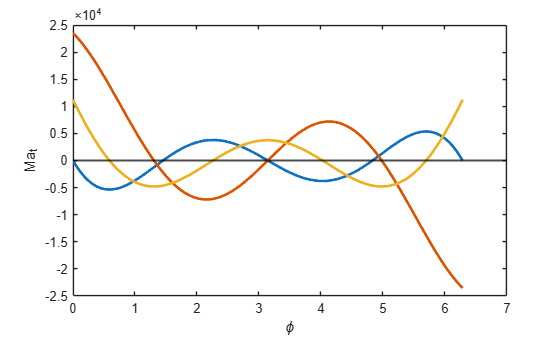

figure; 
plot(phi, Ma_r(:,4), 'LineWidth', 2); hold on  % Ma_r from tangential load
plot(phi, Ma_r(:,5), 'LineWidth', 2); hold on  % Ma_r from tangential load
plot(phi, Ma_r(:,6), 'LineWidth', 2); hold off % Ma_r from tangential load
xlabel('\phi'), ylabel('Ma_t')
yline (0, 'LineWidth', 1.5, 'Color', 'k'); 
grid off;

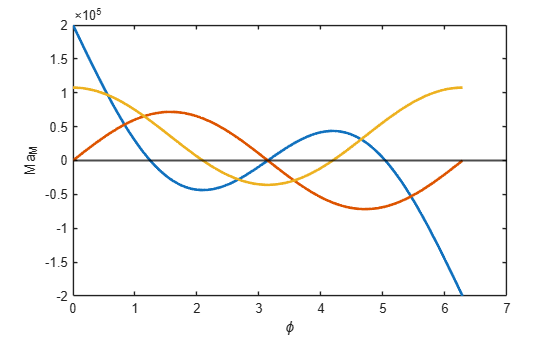

figure; 
plot(phi, Ma_r(:,7), 'LineWidth', 2); hold on  % Ma_r from moment load
plot(phi, Ma_r(:,8), 'LineWidth', 2); hold on  % Ma_r from moment load
plot(phi, Ma_r(:,9), 'LineWidth', 2); hold off % Ma_r from moment load
xlabel('\phi'), ylabel('Ma_M')
yline (0, 'LineWidth', 1.5, 'Color', 'k'); 
grid off;

## Shear Visualization

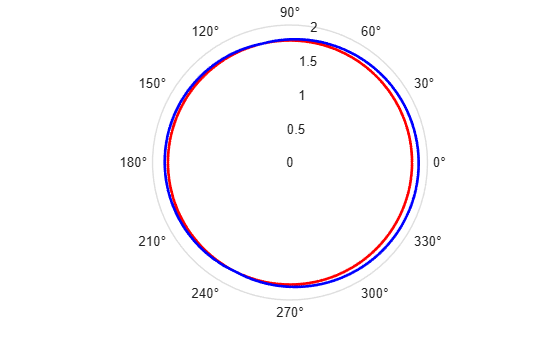

pi = pi;
alpha = -pi/2;

q = (Torque + P*R_fus)/(2*pi_val*R_fus^2) ...
          + (P*cos(phi - alpha))/(pi_val*R_fus) ...
          + (ShearQ*sin(phi - alpha))/(pi_val*R_fus);

scale = 1e-6; % purely for visualization
r_q = R_fus + scale*q;
idx = r_q < R_fus;
r_q(idx) = R_fus + abs(scale*q(idx));
figure
polarplot(phi, R_fus*ones(size(phi)), 'r', 'LineWidth', 2) % fuselage
hold on; grid off;
polarplot(phi, r_q, 'b', 'LineWidth', 2) % shear flow
hold off;